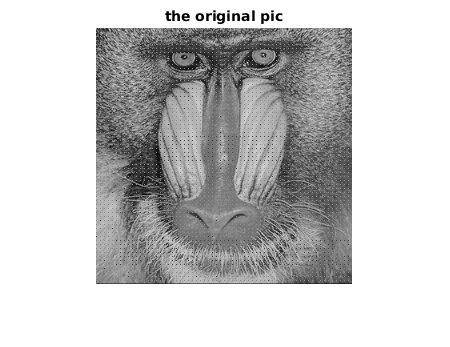

I=imread('mbaboon.bmp');
figure
imshow(I)
title('the original pic')

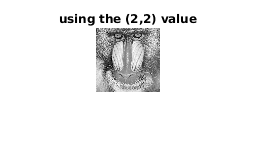


blockSize = [4 4];
twoCrosstwoFunction = @(theBlockStructure) theBlockStructure.data(2,2);
blockImage = blockproc(I, blockSize, twoCrosstwoFunction); 
figure
imshow(blockImage,[])
title('using the (2,2) value')

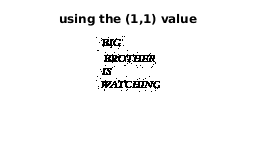



oneCrossonefunction= @(theBlockStructure) theBlockStructure.data(1,1);
blockImage1 = blockproc(I, blockSize, oneCrossonefunction);

imshow(blockImage1,[])
title('using the (1,1) value')

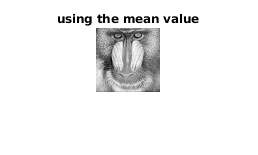


meanFunction = @(theBlockStructure) mean2(theBlockStructure.data(:));
blockImage2 = blockproc(I, blockSize, meanFunction);

imshow(blockImage2,[])
title('using the mean value')